# 論文の実装~Algorithm 1~

## システムのダイナミクス

A = [-1 2; 2.2 1.7];
B = [2; 1.6]

B =     2.0000
    1.6000


C = [1 2];

sys = ss(A, B, C, [], 1)


sys =
 
  A = 
        x1   x2
   x1   -1    2
   x2  2.2  1.7
 
  B = 
        u1
   x1    2
   x2  1.6
 
  C = 
       x1  x2
   y1   1   2
 
  D = 
       u1
   y1   0
 
サンプル時間:  1 seconds
離散時間状態空間モデル。



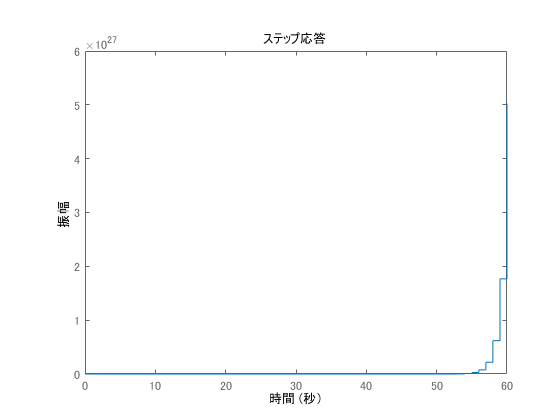

step(sys)

## 学習パラメータ

F = -1;
Q = 6;
R = 1;
gamma = 0.8;


K_0 = [0.3 1.3 0.75];
x_0 = [5; -5];
r_0 = [5];
X_0 = [x_0; r_0];

## その他変数宣言

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];
Q1 = C1'*Q*C1;

## 学習

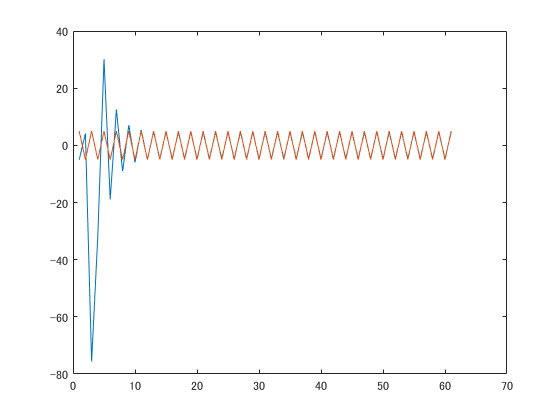

% 初期化
X = X_0;
K1 = K_0;

yList = [C*x_0];
rList = [r_0];

for i = 1 : 60
    % 方策評価，改善
    P = dlyap(sqrt(gamma)*(T-B1*K1)', Q1+K1'*R*K1);
    K1 = (R+gamma*B1'*P*B1)\gamma*B1'*P*T;
    
    % 行動決定
    u = -K1*X;
    
    % 状態遷移
    X = T * X + B1 * u;
    y = C * X(1:2);
    
    r = X(3);
    yList = [yList; y];
    rList = [rList; r];
end

plot(yList);
hold on;
plot(rList);